# WTLSTM fc/cov/~

## Load data

imdsTrain = imageDatastore(fullfile('DataSet','HyperparameterSearch','Train','Img','WTImg'),FileExtensions=".jpg");
imdsTest = imageDatastore(fullfile('DataSet','HyperparameterSearch','Test','Img','WTImg'),FileExtensions=".jpg");

imgSize = size(imread(imdsTrain.Files{1,1}));
sequenceSize = [imgSize(1) imgSize(3) imgSize(2) 1];
sequenceTrain = ones(sequenceSize);
cellTrain = {};
for i =1:numel(imdsTrain.Files)
    img = imread(imdsTrain.Files{i,1});
    sequenceShape = [size(img,1) size(img,3) 1];
    timePiece = ones(sequenceShape);
    for j = 1:size(img,2)
        timePiece = cat(3,timePiece,reshape(img(:,j,:),sequenceShape));
    end
    timePiece = timePiece(:,:,2:end);
    sequenceTrain = cat(4,sequenceTrain,timePiece);
    cellTrain{end+1} = timePiece;
end
XTrain=sequenceTrain(:,:,:,2:end);

sequenceTest = ones(sequenceSize);
cellTest={};
for i =1:numel(imdsTest.Files)
    img = imread(imdsTest.Files{i,1});
    sequenceShape = [size(img,1) size(img,3) 1];
    timePiece = ones(sequenceShape);
    for j = 1:size(img,2)
        timePiece = cat(3,timePiece,reshape(img(:,j,:),sequenceShape));
    end
    timePiece = timePiece(:,:,2:end);
    sequenceTest = cat(4,sequenceTest,timePiece);
    cellTest{end+1} = timePiece;
end
XTest=sequenceTest(:,:,:,2:end);

YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};
% save(fullfile('DataSet','HyperparameterSearch','Train','imgSeqTrain.mat'), 'XTrain', '-v7.3');
% save(fullfile('DataSet','HyperparameterSearch','Test','imgSeqText.mat'), 'XTest', '-v7.3');
save(fullfile('DataSet','HyperparameterSearch','Train','imgSeqCellTrain.mat'), 'cellTrain', '-v7.3');
save(fullfile('DataSet','HyperparameterSearch','Test','imgSeqCellTest.mat'), 'cellTest', '-v7.3');

cellTrain = load(fullfile('DataSet','HyperparameterSearch','Train','imgSeqCellTrain.mat')).cellTrain;
cellTest = load(fullfile('DataSet','HyperparameterSearch','Test','imgSeqCellTest.mat')).cellTest;

trainDs = {cellTrain, YTrain};
testDs = {cellTest, YTest};

## Try different 2nd layer

#### just flatten

numFeatures = [221 3];
numBlocks = 2;
numHiddenUnits = 32;
numResponse = 4;
layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
%                 convolution2dLayer([3 1],numFilter,'Stride',[1 1],'Padding',[1 1 0 0])
        flattenLayer("Name",'flatten')
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

#### fc

layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
%                 convolution2dLayer([3 1],numFilter,'Stride',[1 1],'Padding',[1 1 0 0])
        flattenLayer("Name",'flatten')
        fullyConnectedLayer(32,'Name','fullyconect')
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

#### Cov

layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
        convolution2dLayer([3 1],32,'Stride',[1 1],'Padding',[1 1 0 0])
        flattenLayer("Name",'flatten')        
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

### Train

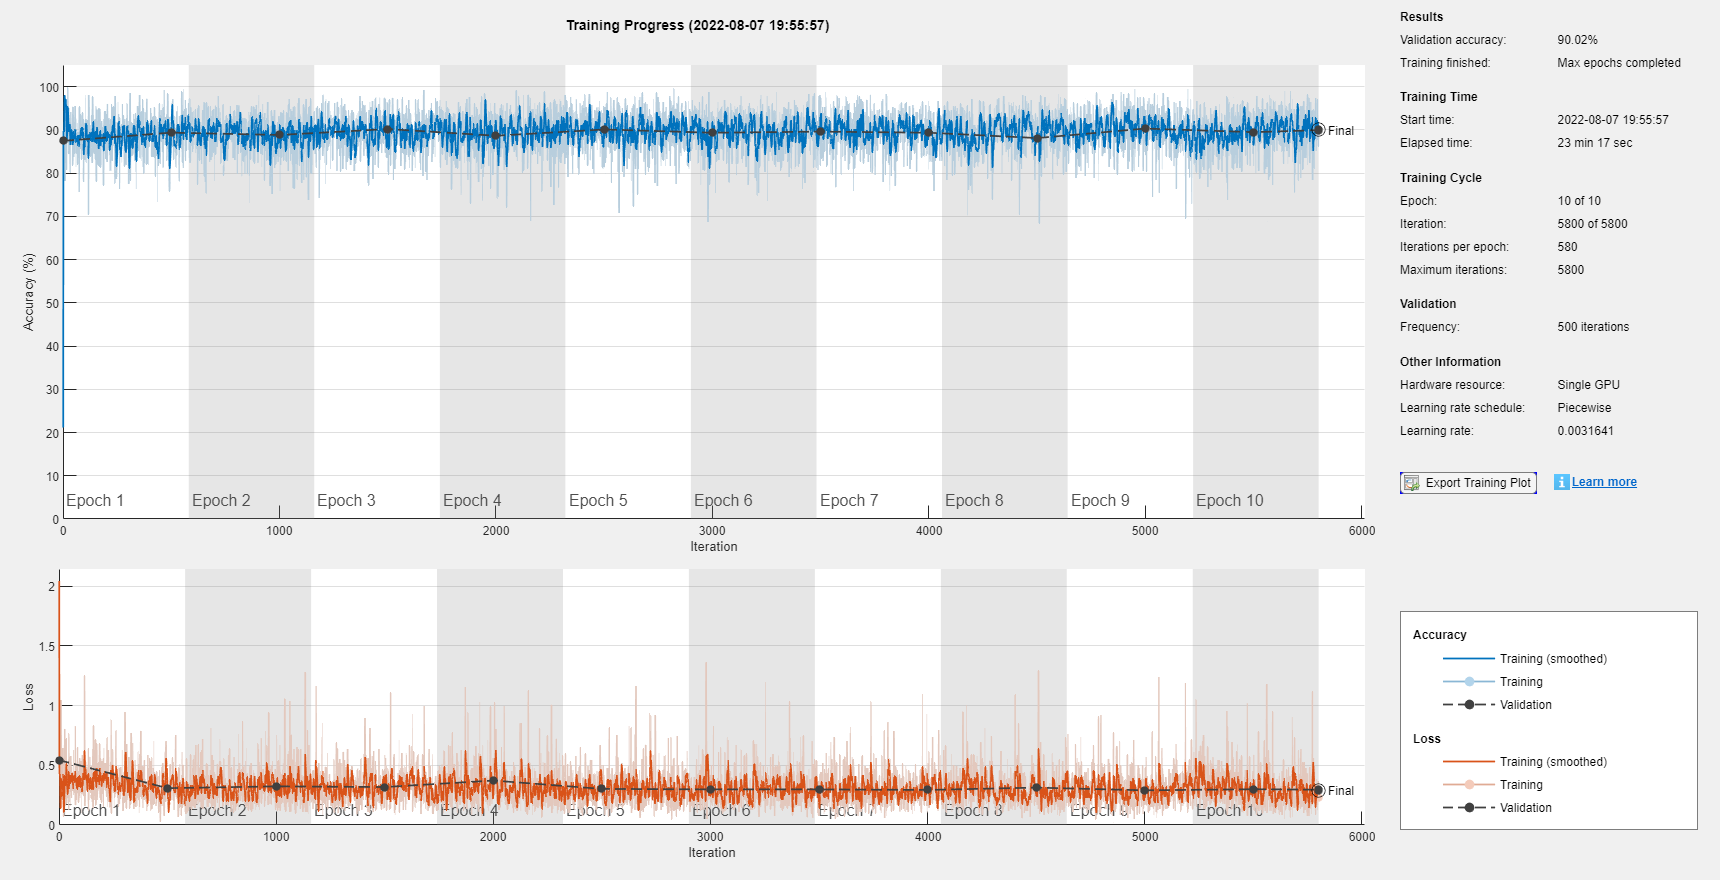

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize',8, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',2, ...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true, ...
    'ValidationData',{cellTrain,YTrain}, ...
    'ValidationFrequency',500);
    


net= trainNetwork(cellTrain,YTrain,lgraph,options);



YPred = classify(netFc, cellTest, "MiniBatchSize",8);

%%%%%%%%%%%%%%%%%
valError = 0;
for k = 1:length(YPred)
    % fix this
    valError = valError + mean(YPred{k} == YTest{k});
end
% return a numeric scalar
valError = 1 - valError/length(YPred);
%%%%%%%%%%%%%%%%%%

save('LSTM/justFl.mat',"net",'-mat');%0.0952
save('LSTM/cov.mat',"netCov",'-mat');%0.1141
save('LSTM/fc.mat',"netFc",'-mat');%0.1101


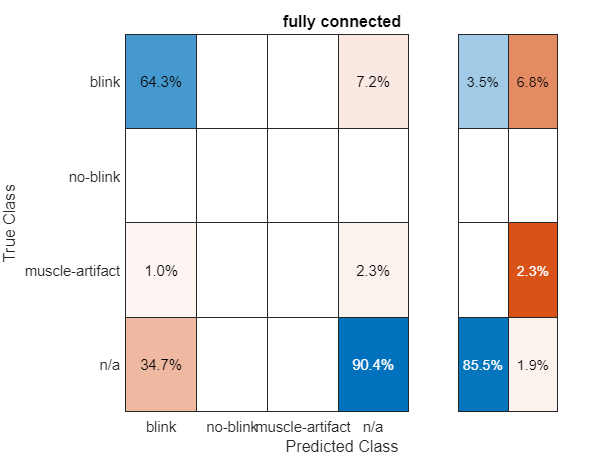



TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized','Title','fully connected','RowSummary','total-normalized');